%an introduction of the topic including pertinent background information.

%an explanation of why this is an interesting research question, placing it in the context of the larger field of physics.

%an explanation of your numerical analysis/computational demostration. Of course, this would be easy in a Jupyter Notebook or MATLAB live script

%plots, graphics, tables, or other appropriate visual representations of the data and results.Of course, these would be easy to include and format in a Jupyter Notebook or MATLAB live script.

%a conclusion summarizing your topic and suggesting further research possibilities.

%a list of sources (7 minimum).

## The Precession of the Perihelion of Mercury

#### History

The majority of Mercury's perihelion advance can be accounted for by the gravitational force of the outer planets of the solar system on Mercury. This effect can be fairly accurately modeled by making each outer planet a ring of constant density. This represents an opposing force centered at the sun and accounts for $532$ arcseconds of the perihelion advance, out of the total $574\ldotp 10\pm 0\ldotp 65$ arcseconds found observationally. This leaves a discrepancy of $43$ arcseconds, which was later explained by Einstein's theory of General Relativity. This was actually one of the major tests of General Relativity which provided experimental confirmation.

#### Computations and Numerical Analysis

Calculated the orbit of Mercury without taking into account any perturbative effects from the planets using the mean anomaly, eccentric anomaly, and true anomaly. The mean anomaly ($M$) is the mean motion ($n$) multiplied by the length of time ($t-\tau$) since the planet last passed its perigee.

$M=n\left(t-\tau \right)=t\sqrt{\frac{M_{\mathrm{sun}} G}{a^3 }}$ if $\tau =0$ (i.e. orbit begins at perhelion)

a = 57909050000; %semi-major axis (m)
e = 0.205630; %eccentricity
msun = 1.9885e30; %sun mass (kg)
G = 6.67408e-11;
t = 0:60*60*24:60*60*24*88; %(s)

M = @(t) t.*(msun.*G./a.^3)^(1/2);

The eccentric anomaly ($E$) is related to the mean anomaly by the following function:


$$M=E-e\;\mathrm{sin}\left(E\right)$$


If all the terms of this equation are moved to one side, $E$ can be solved for using Newton-Raphson's method, which is similar to the romberg technique used to solve integrals. (Function is included at end of paper)

EA = @(E) E-e.*sin(E)-M(t);
EAprime = @(E) 1-e.*cos(E);
E = NRmethod(EA, EAprime, M(t), 1e-16);

The eccentric anomaly at each time can then be used to find the true anomaly ($\theta$) and the cartesian coordinates of Mercury at that time.


$$\cos \left(\theta \right)=\frac{\cos \left(E\right)-e}{1-e\;\cos \left(E\right)}$$



$$\mathrm{sin}\left(\theta \right)=\frac{\sqrt{1-e^2 }\mathrm{sin}\left(E\right)}{1-e\;\mathrm{cos}\left(E\right)}$$


sintheta = @(E) ((1-e^2)^(1/2).*sin(E))./(1-e.*cos(E));
costheta = @(E) (cos(E)-e)./(1-e.*cos(E));

Since the orbit is an ellipse, the distance $r$ from Mercury to the Sun is represented in terms of the true anomaly by the folling equation. The cartesian coordinates can then be derived using $r$, $\cos \left(\theta \right)$, and $\sin \left(\theta \right)$.


$$r=\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}$$



$$x=r\;\mathrm{cos}\left(\theta \right)=\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\left(\frac{\cos \left(E\right)-e}{1-e\;\cos \left(E\right)}\right)$$



$$y=r\;\sin \left(\theta \right)=\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\left(\frac{\sqrt{1-e^2 }\mathrm{sin}\left(E\right)}{1-e\;\mathrm{cos}\left(E\right)}\right)$$


r = @(costheta) a*(1-e^2)./(1+e.*costheta);
x = @(r, costheta) r(costheta(E)).*costheta(E);
y = @(r, sintheta) r(costheta(E)).*sintheta(E);

x1 = x(r, costheta);
y1 = y(r, sintheta);

plot(0, 0, 'y*')
axis([-8e10,6e10,-6e10,6e10])
set(gcf, 'position', [0, 0, 1000, 1000])
set(gca, 'Color', 'k')
hold on
plot(x1, y1, 'Color', 'r', 'marker', '.', 'Linewidth', 1)

If the effects from the other planets and general relativity are not taken into account, the equation for the radius of an ellipse can model the orbit of Mercury.


$$r=\frac{a\left(1-e^2 \right)}{1+e\;\cos \left(\theta \right)}$$


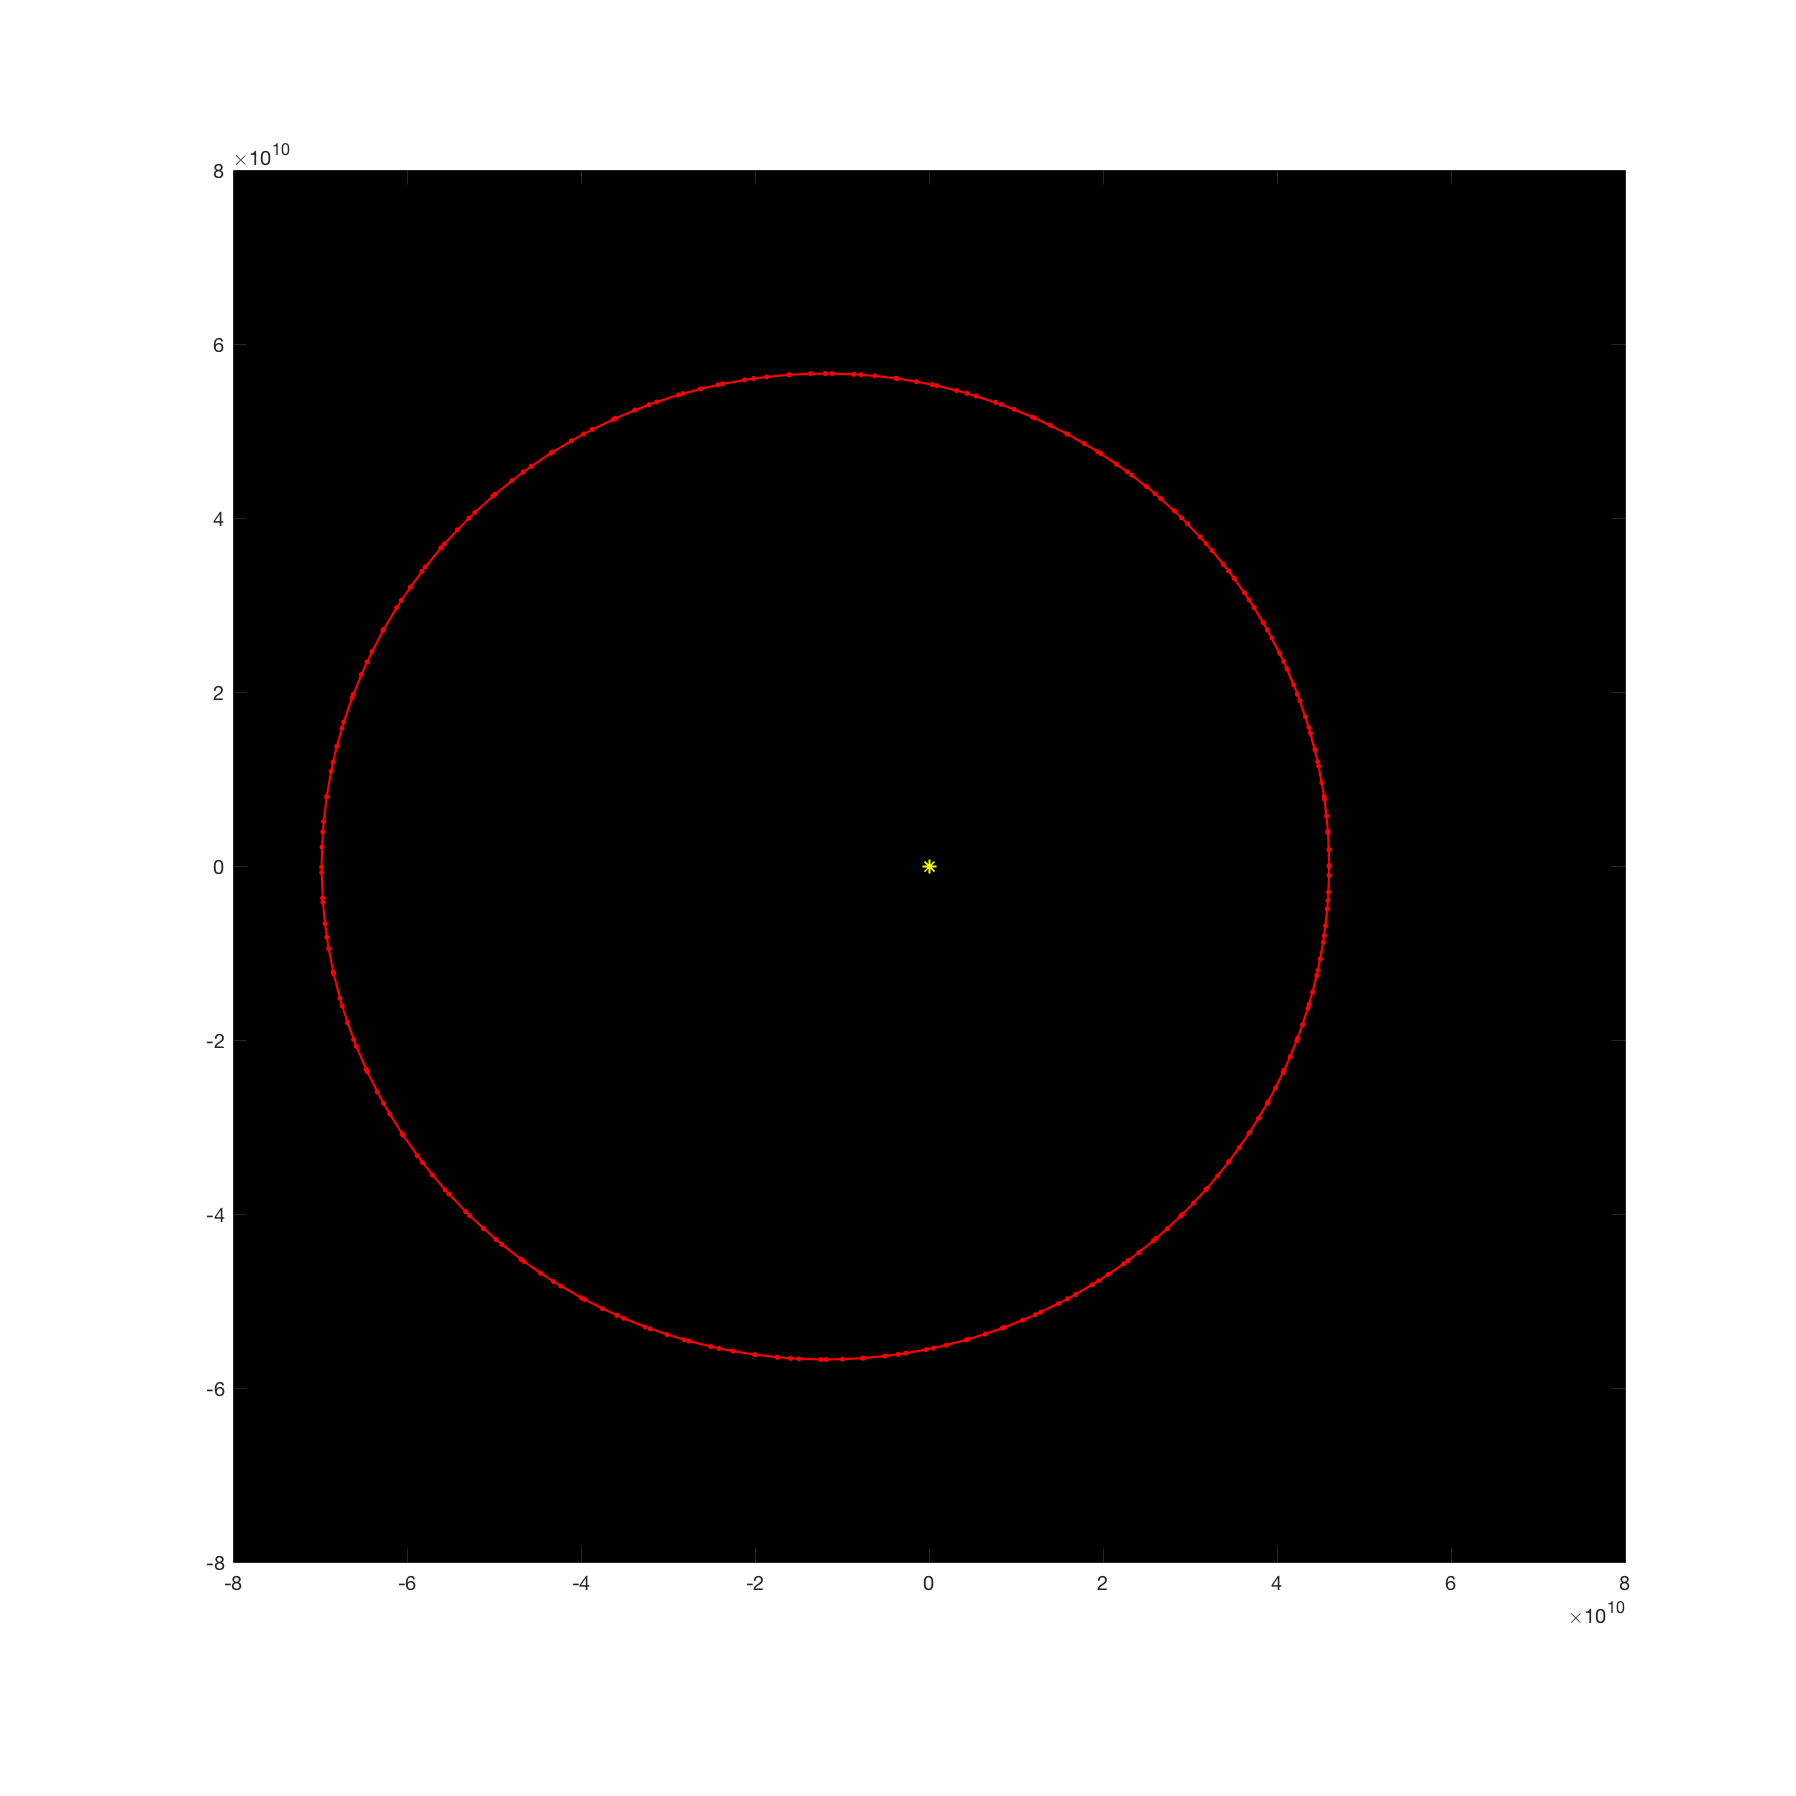

a = 57909050000; %semi-major axis of mercury (m)
e = 0.205630; %eccentricity of merciry's orbit

theta = linspace(0, (2*pi)*(365.25/87.969)*0.24,24*(2*pi)*(365.25/87.969)*0.24); %models one orbit
r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));
%converts polar coords to cartesian
x = @(r, theta) r.*cos(theta);
y = @(r, theta) r.*sin(theta);

plot(0,0,'y*')
set(gca, 'Color', 'k')
axis([-8e10,8e10,-8e10,8e10], 'square')
p1 = plot(x(r(theta), theta), y(r(theta), theta), 'Color', 'r', 'marker', '.', 'Linewidth', 1, "DisplayName", "None");

This method worked well for modeling the orbit of Mercury if only the gravitational force of the sun is taken into account. However, if the gravitational force of the other planets and the effects of general relativity are factored in, an easier approach is to calculate the precession of the orbit using the following formula and then shifting the position of Mercury. This method is oulined in Davis 1982.


$$\Delta \psi =\frac{1}{e}\int_0^{2\pi } g\left(r\right)\mathrm{cos}\left(\theta \right)d\theta$$


$g\left(r\right)$ is the ratio of the perturbing force to the gravitational force of the Sun.

To find $g\left(r\right)$ from another planet:


$$g\left(r\right)=\frac{M_P r^3 }{2M_S R_P \left({R_P }^2 -r^2 \right)}=\frac{M_P {\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^3 }{2M_S R_P \left({R_P }^2 -{\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^2 \right)}$$


Since all the variables in this expression are constants except for $\theta$, this can be integrated to solve for the precession of the orbit over one period.

a = 57909050000; %semi-major axis of mercury (m)
e = 0.205630; %eccentricity of merciry's orbit
msun = 1.9885e30;
mvenus = 4.867e24; %venus mass (kg)
Rvenus = 108208000000; %venus radius (m)
mearth = 5.976e24; %earth mass (kg)
Rearth = 149598023000; %earth radius (m)
mmars = 6.421e23; %mars mass (kg)
Rmars = 227939200000; %mars radius (m)
mjupiter = 1.899e27; %jupiter mass (kg)
Rjupiter = 778.57e9; %jupiter radius (m)
msaturn = 5.686e26; %saturn mass (kg)
Rsaturn = 1433.53e9; %saturn radius (m)
muranus = 8.681e25; %uranus mass (kg)
Ruranus = 2.87503e12; %uranus radius (m)
mneptune = 1.02413e26; %neptune mass (kg)
Rneptune = 4.504e12; %neptune radius (m)
G = 6.67408e-11;
c = 299792458; %speed of light (m/s)
RP = [Rvenus, Rearth, Rmars, Rjupiter, Rsaturn, Ruranus, Rneptune];
MP = [mvenus, mearth, mmars, mjupiter, msaturn, muranus, mneptune];

r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));

g = @(r, RP, MP) -MP.*r.^3./(2.*msun.*RP.*(RP.^2-r.^2));

deltapsiP = 0;
for i = 1:7
    int = @(theta) g(r(theta), RP(i), MP(i)).*cos(theta);
    deltapsiP = deltapsiP + (1/e)*integral(int, 0, 2*pi);
end
fprintf("Orbital precession due to planets: %f arcseconds per orbit; %f arcseconds per century", deltapsiP*(360*3600/(2*pi)), deltapsiP*(365.25*100/87.969)*360*3600/(2*pi))

Orbital precession due to planets: 1.281939 arcseconds per orbit; 532.264989 arcseconds per century

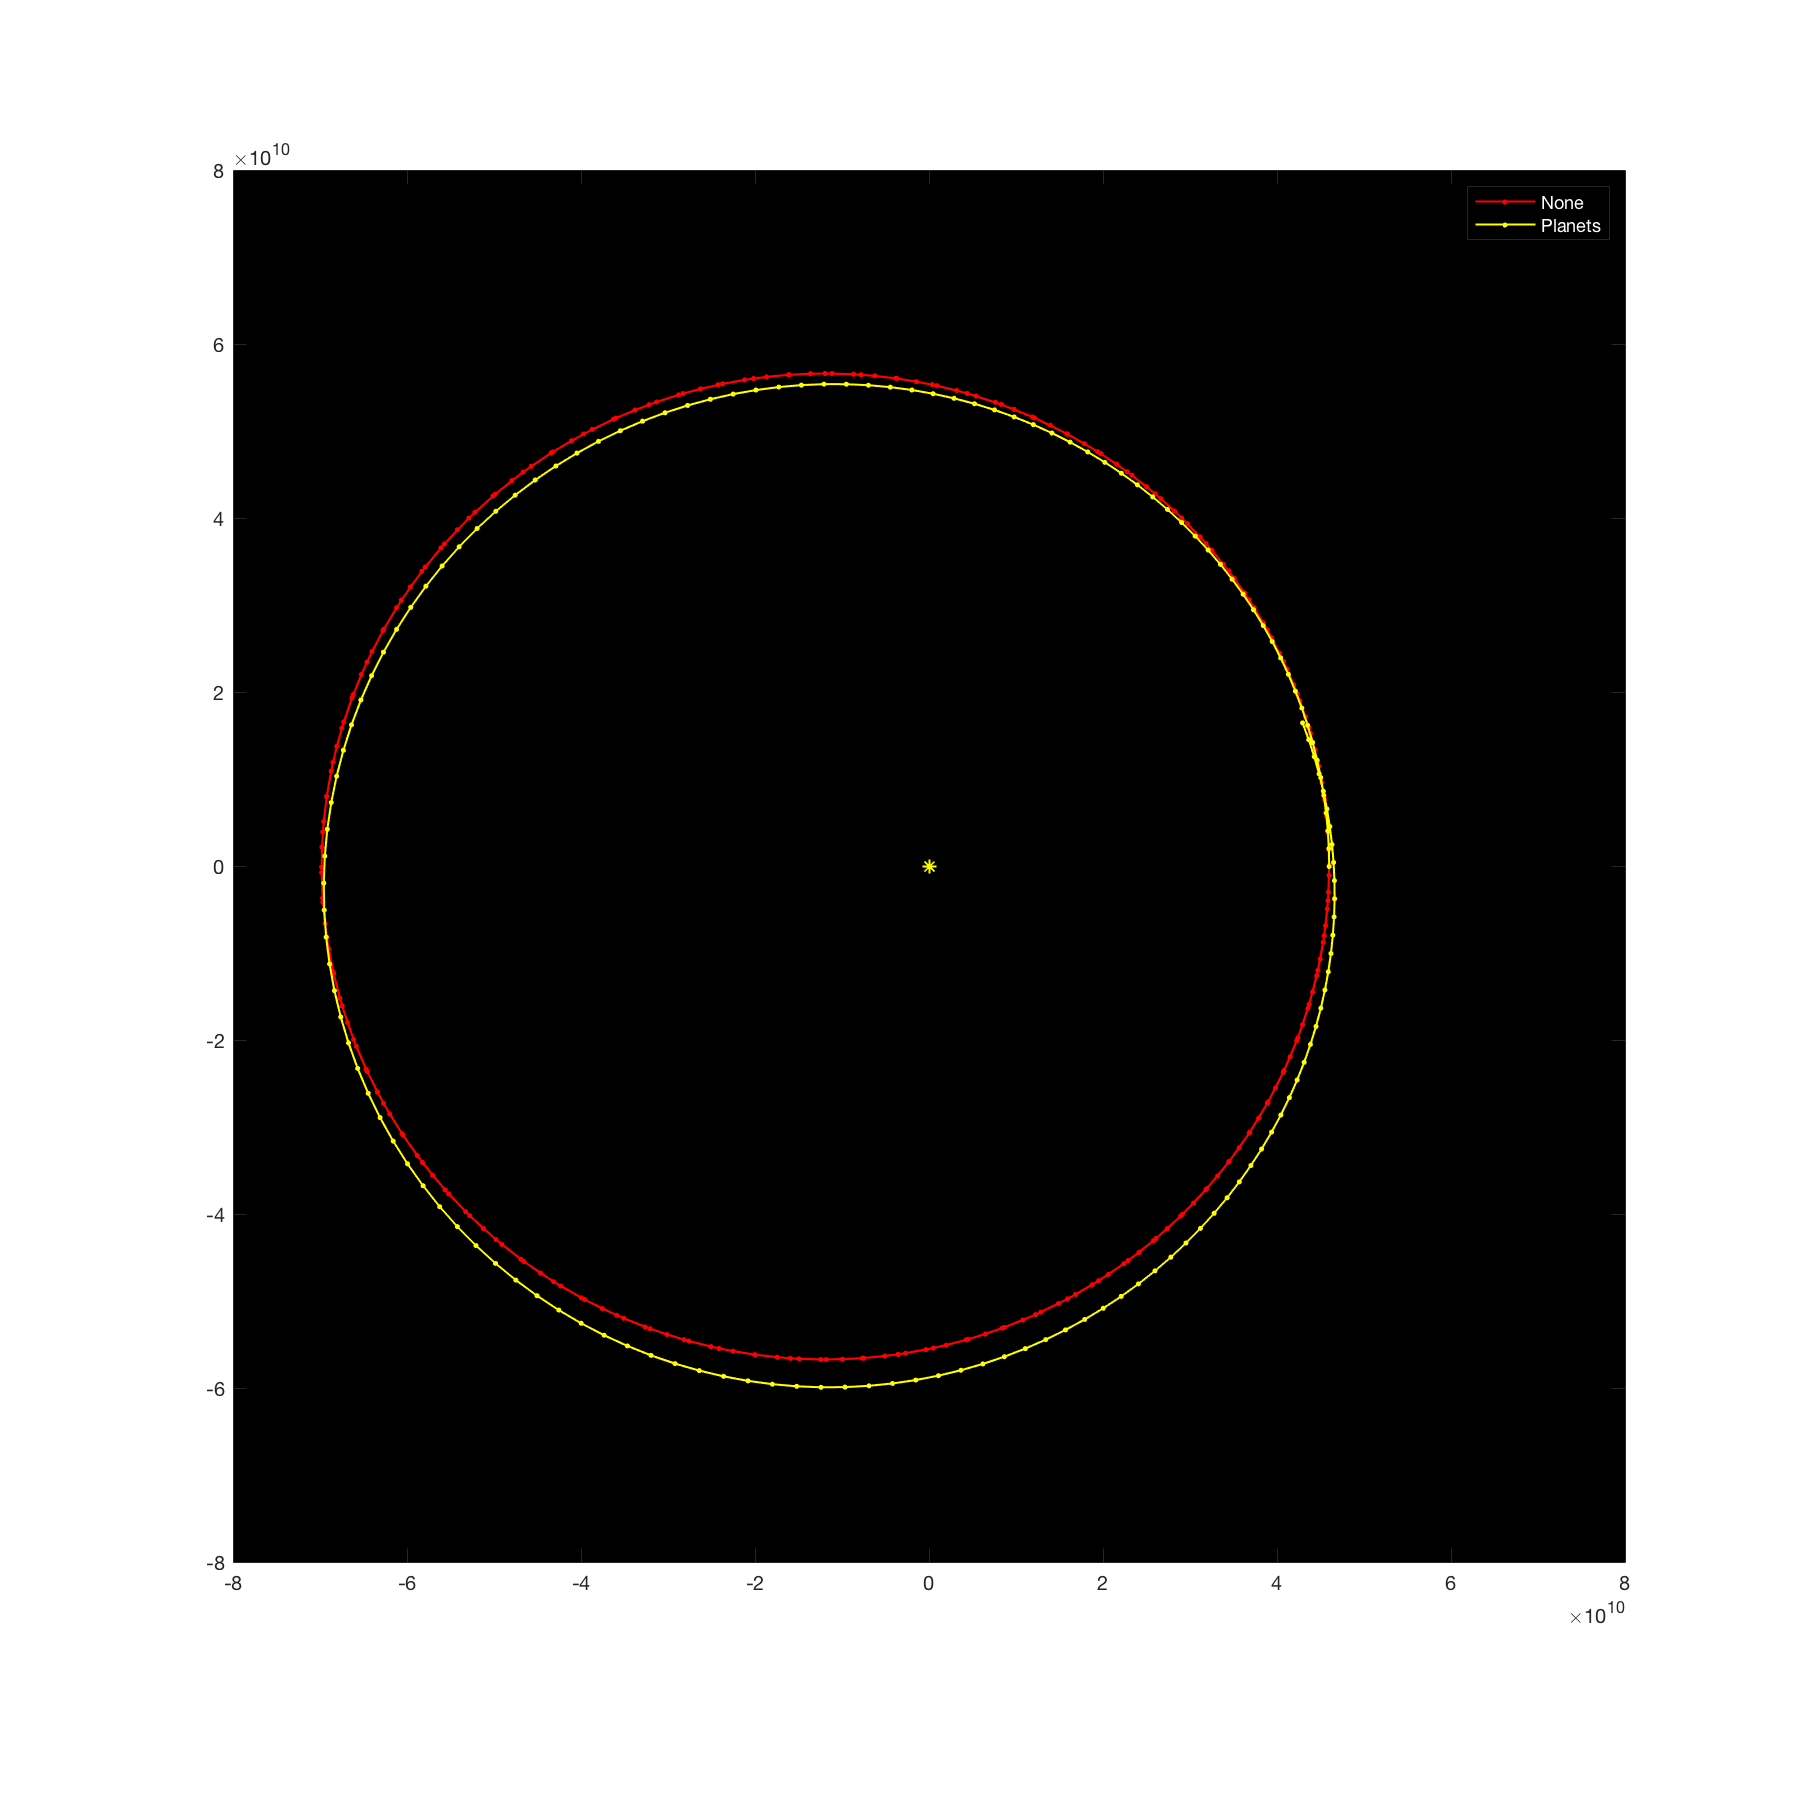

amp = 10000; %amplifies precession so it is visible in plot
x = @(r, theta, deltapsi) r.*cos(theta+amp*theta*deltapsi);
y = @(r, theta, deltapsi) r.*sin(theta+amp*theta*deltapsi);

p2 = plot(x(r(theta), theta, deltapsiP), y(r(theta), theta, deltapsiP), 'Color', 'y', 'marker', '.', 'Linewidth', 1, "DisplayName", "Planets");
legend([p1, p2],'TextColor', 'w')

The effect that general relativity has on the precession of Mercury's orbit can also be represented by $g\left(r\right)$.


$$g\left(r\right)=\frac{3GM_S a\left(1-e^2 \right)}{c^2 r^2 }=\frac{3GM_S a\left(1-e^2 \right)}{c^2 {\left(\frac{a\left(1-e^2 \right)}{1+e\;\mathrm{cos}\left(\theta \right)}\right)}^2 }$$


Again, since this equation is represented in terms of $\theta$, it can be integrated to find the precession of the orbit over one period.

r = @(theta) a.*(1-e.^2)./(1+e.*cos(theta));

g = @(r) 3*G*msun*a*(1-e^2)./(c^2.*r.^2);

int = @(theta) g(r(theta)).*cos(theta);
deltapsiGR = (1/e)*integral(int, 0, 2*pi);
fprintf("Orbital precession due to general relativity: %f arcseconds per orbit; %f arcseconds per century", deltapsiGR*(360*3600/(2*pi)), deltapsiGR*(365.25*100/87.969)*360*3600/(2*pi))

Orbital precession due to general relativity: 0.103519 arcseconds per orbit; 42.981256 arcseconds per century

The sum of these calculations agree with the observed precession of the perihelion of Mercury.

fprintf("Total orbital precession per century: %f arcseconds", (deltapsiP+deltapsiGR)*(365.25*100/87.969)*360*3600/(2*pi))

Total orbital precession per century: 575.246245 arcseconds

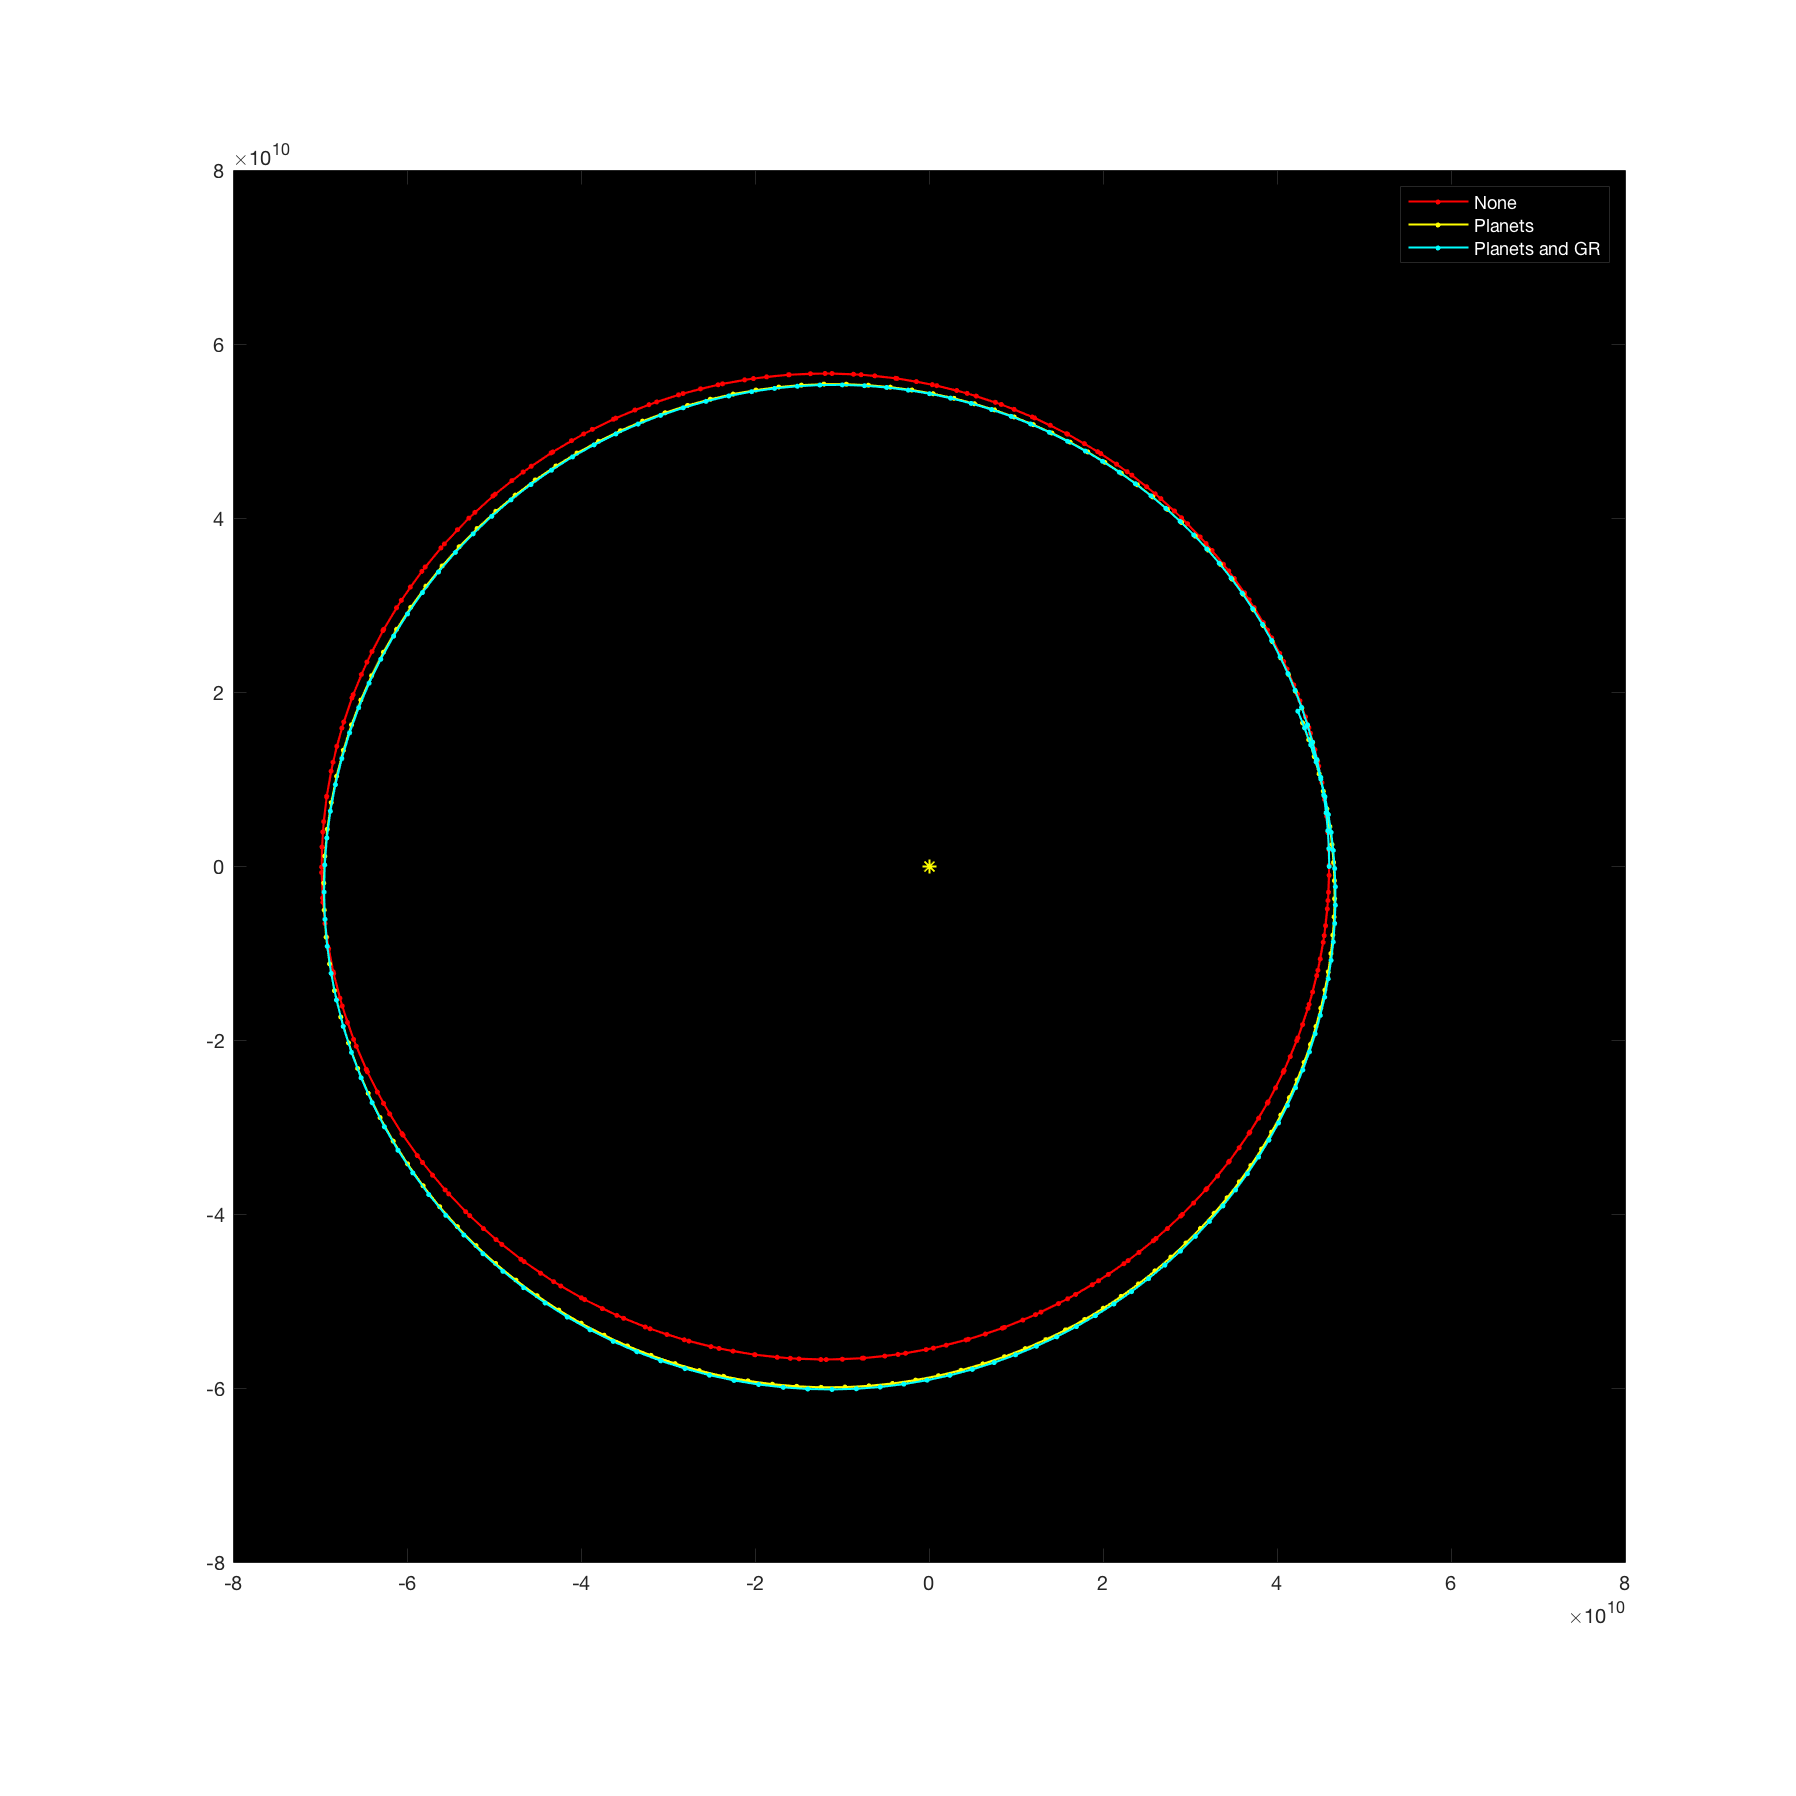

amp = 10000; %amplifies precession so it is visible in plot
x = @(r, theta, deltapsi) r.*cos(theta+amp*theta*deltapsi);
y = @(r, theta, deltapsi) r.*sin(theta+amp*theta*deltapsi);

p3 = plot(x(r(theta), theta, deltapsiP+deltapsiGR), y(r(theta), theta, deltapsiP+deltapsiGR), 'Color', 'c', 'marker', '.', 'Linewidth', 1, "DisplayName", "Planets and GR");
legend([p1, p2, p3],'TextColor', 'w')

#### Sources

B. Davies, *Elementary theory of perihelion precession *(Am. J. Phys. October 1983), p. 909

M. P. Price, W. F. Rush, *Nonrelativistic contribution to Mercury's perihelion precession *(Am. J. Phys. June 1979), p. 531

R. Hakim, *An Introduction to Relativistic Gravitation *(Cambridge University Press 1999)

A. Einstein, *Relativity, the Special and General Theory *(Crown Publishers, New York 1961)

V. A. Chobotov, *Orbital Mechanics *(American Institute of Aeronautics and Astronautics 2002)

Masses and radii of planets and sun from Wikipedia

function E = NRmethod(f, fprime, E0, accuracy)
    E = E0;
    error = -1*(f(E)./fprime(E));
    while abs(error) > accuracy
        error = -1*(f(E)./fprime(E));
        E = E+error;
    end
end